f = sym('phi'); % roll, rotate about b1 or x
t = sym('theta'); % pith, rotate about b2 or y
p = sym('psi'); % yaw, rotate about b3 or z


Perform rotations from the world frame ($\mathcal{A}$) to the body frame ($\mathcal{B}$)

% rotate angle psi about z (yaw the quadcopter)
R_z = [cos(p) -sin(p) 0; 
       sin(p)  cos(p) 0;
       0       0      1]

$$R\_z = \left(\begin{array}{ccc} \cos\left(\psi \right) & -\sin\left(\psi \right) & 0\\ \sin\left(\psi \right) & \cos\left(\psi \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

% rotate angle phi about x (roll the quadcopter)
R_x = [1 0       0; 
       0 cos(f) -sin(f);
       0 sin(f)  cos(f)] 

$$R\_x = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\varphi \right) & -\sin\left(\varphi \right)\\ 0 & \sin\left(\varphi \right) & \cos\left(\varphi \right) \end{array}\right)$$


% Rotate angle thera about y (pitch the quadcopter)
R_y = [ cos(t) 0  sin(t); 
        0      1  0; 
       -sin(t) 0  cos(t)]

$$R\_y = \left(\begin{array}{ccc} \cos\left(\theta \right) & 0 & \sin\left(\theta \right)\\ 0 & 1 & 0\\ -\sin\left(\theta \right) & 0 & \cos\left(\theta \right) \end{array}\right)$$

so the complete rotation from A to B $^\mathcal{A}[R]_\mathcal{B}$is

ARB = R_z*R_x*R_y % the result matches (16.3) in Kumar

$$ARB = \left(\begin{array}{ccc} \cos\left(\psi \right)\,\cos\left(\theta \right)-\sin\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right) & -\cos\left(\varphi \right)\,\sin\left(\psi \right) & \cos\left(\psi \right)\,\sin\left(\theta \right)+\cos\left(\theta \right)\,\sin\left(\varphi \right)\,\sin\left(\psi \right)\\ \cos\left(\theta \right)\,\sin\left(\psi \right)+\cos\left(\psi \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right) & \cos\left(\varphi \right)\,\cos\left(\psi \right) & \sin\left(\psi \right)\,\sin\left(\theta \right)-\cos\left(\psi \right)\,\cos\left(\theta \right)\,\sin\left(\varphi \right)\\ -\cos\left(\varphi \right)\,\sin\left(\theta \right) & \sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\theta \right) \end{array}\right)$$

PID test

The 1D equation of motion for the quadcopter by Newton's 2nd Law: $\sum F = \sum_{i=1}^{4} k_F \omega_i^2-mg=m\ddot{x}$  

Which shows the obvious control input $u=\frac{1}{m}\sum_{i=1}^{4}k_F\omega_i^2-mg$, i.e. the control input is a function of the angular velocity of the four motors.

Then the system is $\ddot{x}=u$, which is a simple 2nd order system. The Laplace transformation with zero initial conditions, $s^2X(s)=U(s)$, gives us the plant transfer function $G(s)=\frac{X(s)}{U(s)}=\frac{1}{s^2}$

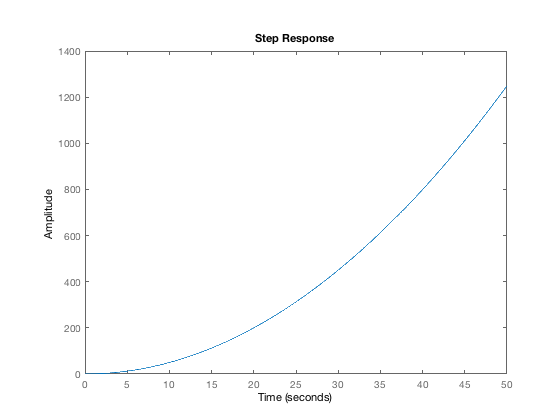

s = tf('s');
sys = 1/s/s;
step(sys)

pidtool(sys)

[https://github.com/ra9hur/Coursera-Aerial-Robotics/blob/master/Week3A/controller.m](https://github.com/ra9hur/Coursera-Aerial-Robotics/blob/master/Week3A/controller.m)

syms L real

f = [1 1; L -L];
inv(f)

$$ans = \left(\begin{array}{cc} \frac{1}{2} & \frac{1}{2\,L}\\ \frac{1}{2} & -\frac{1}{2\,L} \end{array}\right)$$

phi = pi/4;
R_x = [1, 0, 0; 0, cos(phi), -sin(phi); 0, sin(phi), cos(phi)];
pb = [0, 1/sqrt(2), 1/sqrt(2)]';
R_x * pb

ans =          0
    0.0000
    1.0000


R_x' * [0,0,1]'

ans =          0
    0.7071
    0.7071


f = sym('phi');   % roll angle, rotate about b1 or x
t = sym('theta'); % pith angle, rotate about b2 or y
p = sym('psi');   % yaw angle, rotate about b3 or z
R_x = [1 0       0; 
       0 cos(f) -sin(f);
       0 sin(f)  cos(f)];
R_y = [cos(t) 0  sin(t); 
       0      1  0; 
      -sin(t) 0  cos(t)];
R_z = [cos(p) -sin(p) 0; 
       sin(p)  cos(p) 0;
       0       0      1];
R = R_z * R_x * R_y

$$R = \left(\begin{array}{ccc} \cos\left(\psi \right)\,\cos\left(\theta \right)-\sin\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right) & -\cos\left(\varphi \right)\,\sin\left(\psi \right) & \cos\left(\psi \right)\,\sin\left(\theta \right)+\cos\left(\theta \right)\,\sin\left(\varphi \right)\,\sin\left(\psi \right)\\ \cos\left(\theta \right)\,\sin\left(\psi \right)+\cos\left(\psi \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right) & \cos\left(\varphi \right)\,\cos\left(\psi \right) & \sin\left(\psi \right)\,\sin\left(\theta \right)-\cos\left(\psi \right)\,\cos\left(\theta \right)\,\sin\left(\varphi \right)\\ -\cos\left(\varphi \right)\,\sin\left(\theta \right) & \sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\theta \right) \end{array}\right)$$